**Cystinosis Disease Detector**

Loading the data:

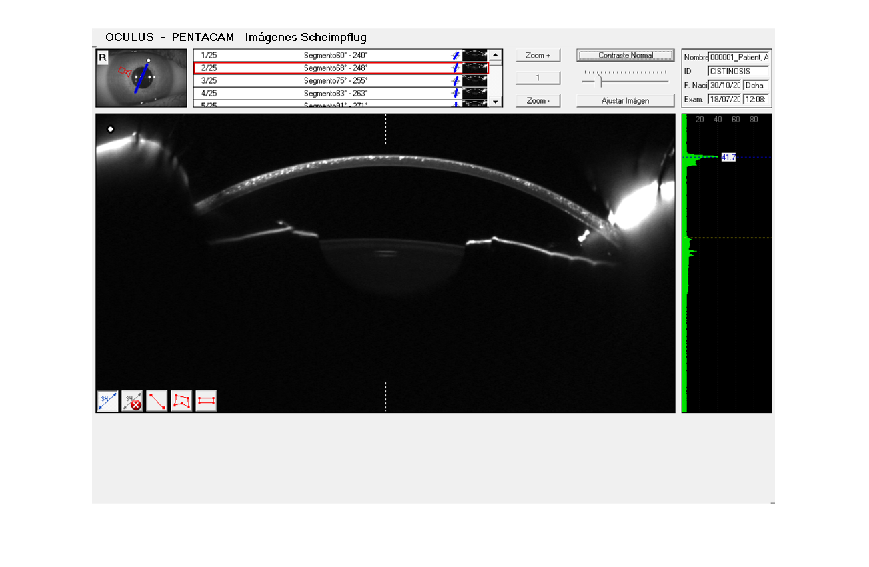

I = imread( '../data/OD1con_Cistinosis/CISTINOSIS_20160718_120806_PENTACAM_R_02.BMP' );
figure,
imshow( I );

Pre-processing: 

I = rgb2gray(I);
I = imcrop( I,[0, 130, 870, 410] );

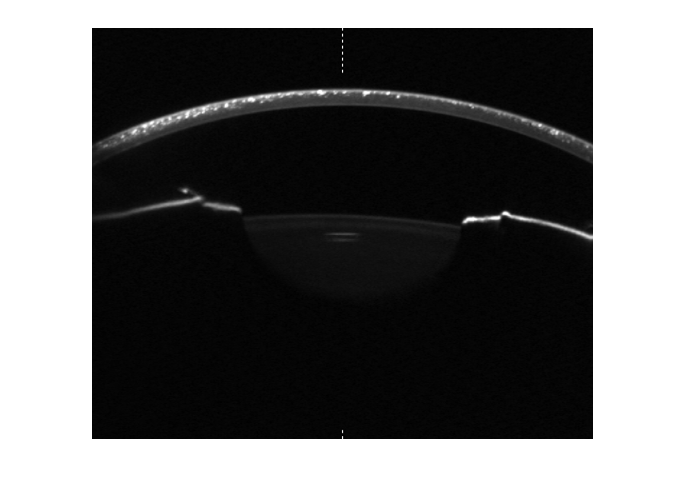

%getting the first 10 rows
croped = imcrop( I, [0, 0, size(I,2), 10] );
bin = imbinarize( croped,0.35 );
%finding the eye center
[row, column] = find( bin, 1, 'last');
%creating a ROI
I = imcrop(I, [column-250, 0 , 250*2, size(I,1)]);
imshow( I );

Localització dels objectes: segmentar la imatge original per diferenciar els objectes d’interès.

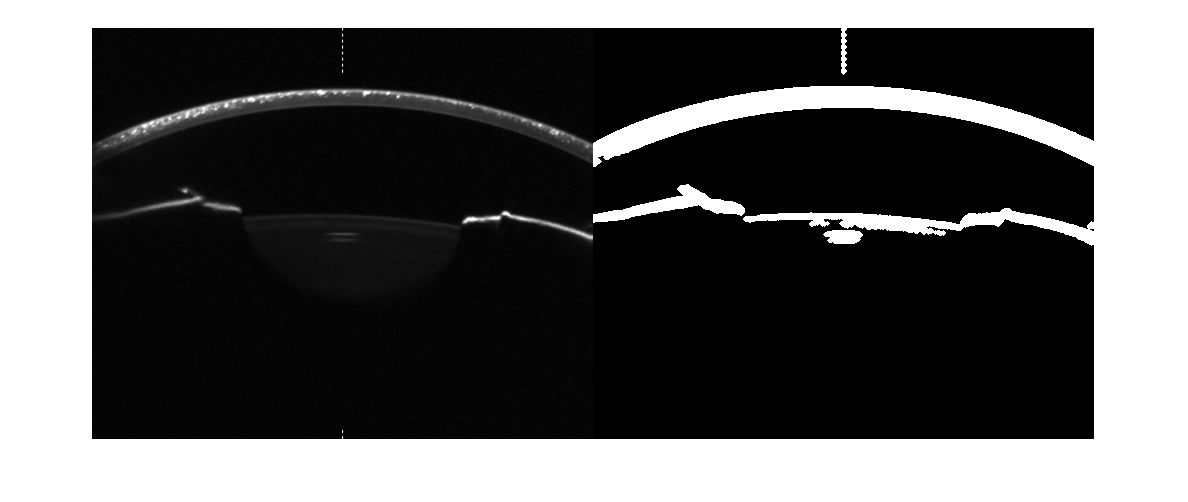

%localitzem la cornia
se = strel( 'disk', 2 );

I_pin_b = imbinarize( I, threshold );
I_pin_b = imdilate( I_pin_b, se );
%filling the holes in the image (crystals)
I_pin_b = imfill( I_pin_b,'holes');
%removing samall objects from binary image
I_pin_b = bwareaopen( I_pin_b, 60 );
figure,
imshowpair( I, I_pin_b, 'montage' );   

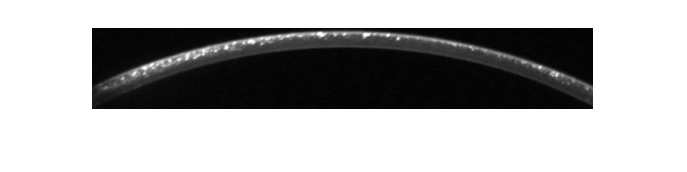

% Apply regionprops to the binary mask
s = regionprops( I_pin_b, 'BoundingBox');
% Get the bounding box property
bb = floor( s(1).BoundingBox );
% Extract out the object from the segmented image
cornea = I( bb(2)+1:bb(2)+bb(4), bb(1)+1:bb(1)+bb(3) );
figure,
imshow( cornea )

Aplanem la cornea

threshold = 0.1;
cornea_bin = imbinarize(cornea, threshold);
[rows, cols] = size( cornea );

for j = 1:cols
    i = 1;
    new_i = 1;
    while cornea_bin(i,j) < 1
        i=i+1;
    end
    for i = i:rows
        cornea(new_i,j) = cornea(i,j);
        cornea(i,j) = 0;
        new_i = new_i+1;
    end
end

I_pin_b = imbinarize( cornea, threshold );
s = regionprops( I_pin_b, 'BoundingBox');
bb = floor( s(1).BoundingBox );
cornea = cornea( bb(2)+1:bb(2)+bb(4), bb(1)+1:bb(1)+bb(3) );
%imshow( cornea );

Amb la informació extreta de la imatge realitzar la tasca demanada.

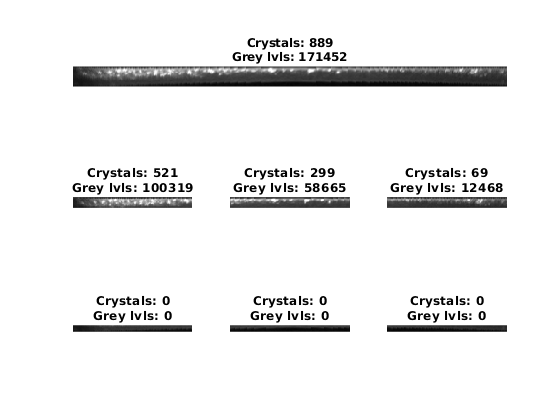

nrows = size(crystals, 1);
ncols = size(crystals, 2);
c_stp = ncols/3;
height_limit = 15;

sections = cell( 6, 1);
sections{1} = imcrop( cornea, [0, 0, c_stp, height_limit] );
sections{2} = imcrop( cornea,[c_stp+1, 0, c_stp, height_limit] );
sections{3} = imcrop( cornea, [c_stp*2+1, 0, c_stp, height_limit] );
sections{4} = imcrop( cornea, [0, height_limit, c_stp, nrows] );
sections{5} = imcrop( cornea,[c_stp+1, height_limit, c_stp, nrows] );
sections{6} = imcrop( cornea, [c_stp*2+1, height_limit, c_stp, nrows] );

crystals = imbinarize( cornea, 0.625 );
crystals_sections = cell( 6, 1);
grey_sections = cell( 6, 1);

figure,
subplot(3,3,[1,2,3]);
imshow(cornea);
% getting the crystals in the cornea
[ counts, binLocations ] = imhist( crystals );
%counting the grey level in the crystals
grey = bsxfun( @times, cornea, uint8(crystals) );
[ counts2, binLocations2 ] = imhist( grey );
grey_lvl = 0;
for j = 1:size( counts2 )
    grey_lvl = grey_lvl + counts2(j)*binLocations2(j);
end
tit = sprintf("Crystals: %i\nGrey levels: %i", counts(2), grey_lvl );
title( tit );

for i=1:6
    subplot(3,3,3+i);
    imshow( sections{i} );
    %counting the crystals
    bin = imbinarize( sections{i}, 0.625 );
    [ counts, binLocations ] = imhist( bin );
    crystals_sections{i} = counts(2);
    %counting the grey level in the crystals
    grey = bsxfun( @times, sections{i}, uint8(bin) );
    [ counts, binLocations ] = imhist( grey );
    tmp = 0;
    for j = 1:size( counts )
        tmp = tmp + counts(j)*binLocations(j);
    end
    grey_sections{i} = tmp;
    tit = sprintf("Crystals: %i\nGrey lvls: %i", crystals_sections{i}, grey_sections{i} );
    title( tit );
end